% Load the pre-trained model
load Neural_Networks\5-signs\resnet_18\resnet.mat;

% Ask the user to select a folder containing the images
inputFolder = uigetdir(pwd, 'Select the folder containing images');

% Load the test dataset
signds = imageDatastore(inputFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Split the dataset into training and testing sets
[signTrain, signTest] = splitEachLabel(signds, 0.8, "randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224], signTrain);
resizeTestImgs = augmentedImageDatastore([224 224], signTest);

% Set the number of classes
numClasses = numel(categories(signds.Labels));

% Set training options
opts = trainingOptions("sgdm", "InitialLearnRate", 0.001, "MaxEpochs", 5, "VerboseFrequency", 2);

% Train the network
[Network1, info] = trainNetwork(resizeTrainImgs, resnet, opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:38 |        5.47% |       3.3212 |          0.0010 |
|       1 |           2 |       00:01:10 |       10.16% |       3.1117 |          0.0010 |
|       1 |           4 |       00:02:41 |       10.16% |       2.9287 |          0.0010 |
|       1 |           6 |       00:04:33 |       28.91% |       2.1285 |          0.0010 |
|       1 |           8 |       00:06:34 |       29.69% |       1.9611 |          0.0010 |
|       1 |          10 |       00:08:09 |       52.34% |       1.4011 |          0.0010 |
|       1 |          12 |  

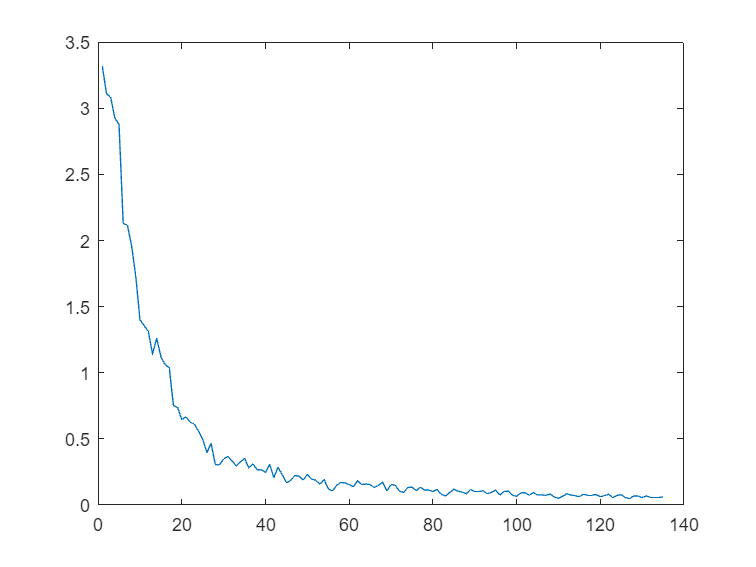


% Plot training loss
plot(info.TrainingLoss);


% Save the "signTest" dataset in respective folders
outputTestFolder = "D:\college\FYP\test_images\output"; % Change this path as per your requirement

% Delete previous output
if exist(outputTestFolder, 'dir') 
  rmdir(outputTestFolder, 's') 
end


for i = 1:numel(signTest.Files)
    imgPath = signTest.Files{i};
    [~, imgName, imgExt] = fileparts(imgPath);
    imgLabel = char(signTest.Labels(i));
    outputFolder = fullfile(outputTestFolder, imgLabel);
    
    % Create the class label folder if it doesn't exist
    if ~exist(outputFolder, 'dir')
        mkdir(outputFolder);
    end
    
    % Copy the image to the respective folder
    outputImgPath = fullfile(outputFolder, strcat(imgName, imgExt));
    copyfile(imgPath, outputImgPath);
end

% Evaluate Performance
signPrediction = classify(Network1, resizeTestImgs);
signActual = signTest.Labels;

% Calculate accuracy
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect / numel(signPrediction);

% Display accuracy
fprintf("Accuracy: %.2f%%\n", fracCorrect * 100);

Accuracy: 96.66%


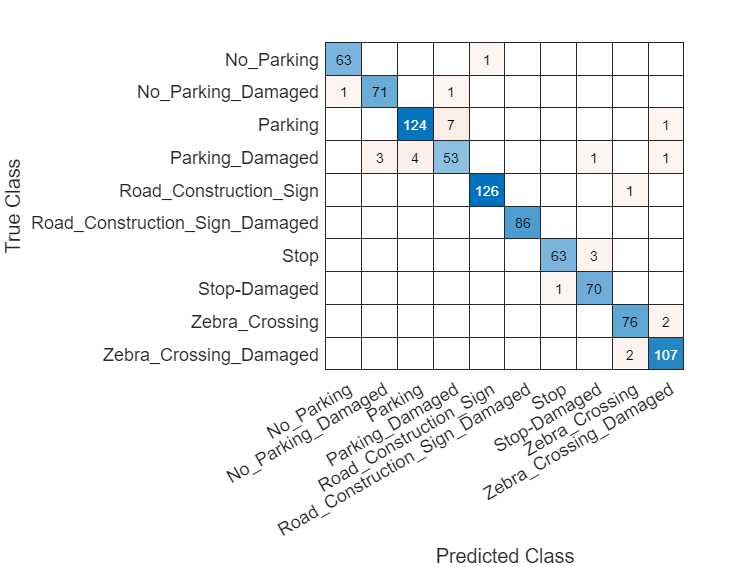


% Confusion Chart
confusionchart(signActual, signPrediction);